# Dynamic Structural Econometrics -- CCP estimation with finite dependence

**Introduction.** This file and its companion file on finite dependence are practical guides that implement conditional choice probability estimators for dynamic discrete choice models. The models included are the bus engine replacement model of Rust (1987) and, in the companion file, a life cycle model of human capital in the style of Keane and Wolpin (1997). The goal is to increase familiarity with the methods used and some of the computational tools and tricks employed when obtaining structural estimates of these types of models. I assume that you have never estimated a dynamic discrete choice model using two-step methods/conditional choice probabilities before this week's lectures, and these notes walk through the procedures step-by-step. 

*Disclaimer:* This file has been written with an emphasis on clarity. In particular, this means that (i) the file is completely self-contained in the sense that all necessary functions are defined within the file (as opposed to be stored as separate .m files) and (ii) code has not been optimized for performance. 

## 1. Bus engine replacement 

We consider the problem of Harold Zurcher studied in Rust (1987). Zurcher maintains a fleet of buses. Maintenance on the buses becomes more costly as the bus engines accumulate mileage. Replacing the engines effectively resets the mileage on the bus and lowers the maintenance cost; however, replacing the engines is much more costly than a single maintenance. The problem facing Zurcher is to decide *when* to replace the engines: replacing the engines too early generates high costs through expensive engine replacements, while waiting too long means that maintenance becomes excessively costly over the long term.

We assume that, as in Rust (1987), we have monthly data on bus maintenance records. This includes data on a set of buses $\mathcal{N} = \{1,...,N\}$ over $T$ months. The observations include mileage readings $x_t$ for each bus and and indicator $d_t$ for whether the engine has been replaced.

### 1.1 Model

- Time is discrete, with $t=1,2,...,\overline{T}$ denoting each period, with $\overline{T} = \infty$.

- Each period, Harold Zurcher chooses between two actions. He can either replace the bus engine, $d_{1t}=1$, or not replace $d_{2t}=1$. These are mutually exclusive, so that $d_{1t} + d_{2t} = 1$.

- Zurcher's payoff depends on a single state variable $x_t$ that represents the mileage of the bus. Mileage advances by a random amount if the bus engine is not replaced and is set to zero if the bus engine is replaced. Denote by $f_d(x_{t+1} | x_t)$ the distribution over next period mileage conditional on current mileage after making choice $d$. When the bus engine is replaced, mileage resets to zero, so that $f_1(x_1 | x_t)=1$ for all $x_t$. Mileage accumulation when the engine is not replaced follows a discrete analog of the exponential distribution up to some maximum mileage $\overline{x}$ where mileage increment is $\Delta_x$.


$$f_2(x_{t+1} | x_t) = \begin{cases} \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big) & \mbox{ for } \ d_{t}=2 \ \mbox{ and } \ x_t \leq x_{t+1} \leq \overline{x}, \\ \exp\big(-(\overline{x} - x_t)\big) & \mbox{ for } \ x_{t+1}>=\overline{x},  \\ 0 & \mbox {otherwise.} \end{cases}$$


- In addition to mileage $x_t$, there is a permanent and observable bus-specific type $s \in \{1,..,S\}$. Assume that the deterministic component of flow payoffs for each action $j=1,2$ for a bus of type $s$ are given by


$$u_{1t}  =  0$$



$$u_{2t}  =   \theta_1 + \theta_2 x_t + \theta_3 s$$


- Payoffs also have an additively separable idiosyncratic component $\epsilon_{jt}$ so that the total flow payoff from choice $j$ in period $t$ is $u_{jt}(x_t) + \epsilon_{jt}$. We assume that $\epsilon_{jt}$ are i.i.d draws from a  Type I EV distribution.

- Denoting the optimal decision rule at $t$ by $d^o_t(x_t, \epsilon_t) = [d^o_{1t}(x_t,\epsilon_{1t}), \ d^o_{2t}(x_t,\epsilon_{2t})]$, we define the ex-ante value function for state $x_t$ in period $t$ as


$$V_t(x_t) \equiv E \Big\{\sum_{\tau=t}^{\overline{T}} \sum_{j=1}^2 \beta^{\tau - t - 1} d^o_{jt}(x_{\tau} \epsilon_{\tau}) (u_{j\tau}(x_{\tau}) + \epsilon_{j\tau})  \Big\}$$


- The conditional value function $v_{jt}(x_t)$ is the value function for choice $j$ in period $t$ and state $x_t$ less the utility shock $\epsilon_{jt}$. In the case of Zurcher's bus engine replacement problem, these functions can be expressed as 


$$v_{1}(x_t) = \beta \sum_{x=1}^{\overline{x}} V(x) f_1(x \ | x_{t+1})$$



$$v_{2}(x_t) = \theta_1 + \theta_2x_t + \theta_3 s + \beta \sum_{x=1}^{\overline{x}} V(x) f_1(x \ | x_{t+1})$$


- Note that all $t$ subscripts have been removed from value functions and state transitions: this is a stationary, infinite horizon problem.

- In the binary choice setting with Type I EV preference shocks we can express conditional choice probabilities very simply:


$$p_2(x_t) = \mbox{Pr}(v_2(x_t) + \epsilon_{2t} \geq v_1(x_t) + \epsilon_{1t}) \ = \ \mbox{Pr}\big(\epsilon_{1t} - \epsilon_{2t} \leq v_2(x_t) - v_1(x_t)\big) \ = \ \frac{\exp\Big(v_2(x_t) - v_1(x_t)\Big)}{ 1 + \exp\Big(v_2(x_t) - v_1(x_t))\Big)}$$


- Representation: finally, we can use the results of Hotz and Miller (1993) to express the difference between the value function $V_t(x_t)$ and conditional value function $v_{j}(x_t)$:


$$V(x_t) - v_{j}(x_t) = \psi_j(p(x_t)), \quad$$
 

where $\quad \psi_j(p(x_t)) = \gamma - \log(p_j(x_t))$ when $\epsilon_{ijt} \sim$ Type I EV, where $\gamma \approx 0.577$ is the Euler-Mascheroni constant. 

#### Representation and identification

The mapping between the difference conditional value functions and the conditional choice probabilities $v_j(x_t) - v_k(x_t) = \psi_k(p(x_t)) -\psi_j(p(x_t))$ forms the basis for representation and identification. To generate the conditions that establish identification, we use the restrictions imposed on the utility function. In our case, we have assumed that $u_1(x)=0$ for all states $x \in X$. Define $\kappa_{\tau}$ as the distribution over state variables reached after $\tau - t$ periods with respect to the choice sequence $\{d^*_{jt}\}$. 


$$\kappa_{\tau}(x_{\tau +1} | x_t, j) = \begin{cases} f_{j}(x_{t+1} | x_t) & \mbox{if } \ \tau=t+1 \\ \sum_{x_{\tau} \in X} \sum_{k\in \{1,2\}} d^*_{k\tau} \ f_k(x_{\tau+1} | x_{\tau})\kappa_{\tau-1}(x_{\tau} | x_t, j)  & \mbox{otherwise.} \end{cases}$$


In our setting, we will define $d^*_{1\tau} = 1$, i.e., all the reference choice in each period is to replace the engine. Repeated application of $v_j(x_t) - v_k(x_t) = \psi_k(p(x_t)) -\psi_j(p(x_t))$ using replacement as the reference choice in each period $\tau \geq t+1$generates that 


$$u_2(x_t) = \psi_1(x_t) - \psi_2(p(x_t)) \\ \qquad \quad + \sum_{\tau = t+1}^T \sum_{x_\tau \in X} \beta^{\tau - t} \psi_1(x_{\tau})\left[ \kappa_{\tau-1}(x_{\tau} | x_t, 1) - \kappa_{\tau-1} (x_{\tau} | x_t, 2) \right]$$


This equation establishes identification of $u_2(x)$ for each $x \in X$: everything on the right-hand side is known ($\psi(\cdot), \ \beta$) or can be estimated ($p(\cdot), \kappa(\cdot | \cdot)$). It is useful to "stack" the moment condition equations for each state $x$ and express the moment conditions in matrix form. 


$$\mathbf{u}_j = \left[ \begin{array}{c} u_j(x_1) \\ \vdots \\ u_j(x_X) \end{array} \right], \qquad F_j = \left[ \begin{array}{c c c} f_j(x_1 | x_1) & \cdots & f_j(x_X | x_1) \\ \vdots & \ddots & \vdots \\ f_j(x_X | x_1)  & \cdots & f_j(x_X | x_X) \end{array} \right], \qquad \Psi_{j} = \left[ \begin{array}{c} \psi_j(p(x_1)) \\ \vdots \\ \psi_j(p(x_X)) \end{array} \right]$$


With this matrix representation, we can write the moment conditions in matrix form $\mathbf{u}_2 = \Psi_1 - \Psi_2 - \mathbf{u}_1 + \beta (F_1 - F_2)(\Psi_1 + \mathbf{u}_1) +\sum_{\tau = t+2}^T \beta^{\tau - t+1} F_1(\Psi_1 + \mathbf{u}_1)$


$$\mathbf{u}_2 = \Psi_1 - \Psi_2 -\mathbf{u}_1 + \beta \Big(F_1 - F_2 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1 + \mathbf{u}_1\Big)$$


(*Note: A derivation for a similar matrix representation for the ex-ante value function in stationary infinite horizon models is contained in Arcidiacono and Ellickson (2011), and forms the bases for many other estimators.)*

### 1.2. Data

clc; clear
rng(2022);

x_min = 0.0 ; x_max = 15.0; 
delta_x = 0.05; 
x_len = (x_max-x_min)/delta_x+1;

We have set $\overline{x} = 15$ and $\Delta_x = 0.05$. With mileage starting at zero, there are 301 state values.

format shortG
x = linspace(x_min, x_max, x_len);
StatesTable = table((1:10)',x(1:10)','VariableNames',{'State index','State value'})

StatesTable = 10×2 table
    State index    State value
    ___________    ___________

         1               0    
         2            0.05    
         3             0.1    
         4            0.15    
         5             0.2    
         6            0.25    
         7             0.3    
         8            0.35    
         9             0.4    
        10            0.45    


Knowing the state values is needed for calculating the flow payoffs $u_j(x)$, but for nearly every other calculation we are primarily interested in the state's index. Calculating the probability of transitioning from one state to another requires referring to the relevant row and column indices in the state transition matrix $f$. Recall that $f_2(x_{t+1} | x_t) =  \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big)$ for $x_{t+1} \leq 25$. We can define the state transition matrix in two steps. First, we assign the probabilities for each state $x<25$, and then we lump all of the leftover probability from mileage larger than $25$ into the last state.

x_tday = repmat(x, [x_len,1]);
x_next = x_tday';                                      
f = (x_next >= x_tday)' .* exp(- (x_next - x_tday)') .* (1 - exp(-delta_x)); 
f(:,end) = 1 - sum(f(:,1:(end-1)), 2); % The last column is set so that the sum of probs is 1
F = cumsum(f(:,:), 2);

F2=f;
F1=zeros(size(f));
F1(:,1)=1;
emc = double(eulergamma);
F2(1:10,1:10)

ans =     0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361    0.0344    0.0327    0.0311
         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361    0.0344    0.0327
         0         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361    0.0344
         0         0         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361
         0         0         0         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380
         0         0         0         0         0    0.0488    0.0464    0.0441    0.0420    0.0399
         0         0         0         0         0         0    0.0488    0.0464    0.0441    0.0420
         0         0         0         0         0         0         0    0.0488    0.0464    0.0441
         0         0         0         0         0         0         0         0    0.0488    0.0464
         0         0         0         0         0         0         0         0     

Defined in this way, each row $i$ of $f$ corresponds to the probability distribution over states conditional on state $i$. The first row is the distribution over next period states conditional on the bus engine having a mileage of zero. The probability of remaining at zero is $\mbox{Pr}(x_{t+1} = 0 | x_t = 0) = f_2(1,1) = 0.0488$, the probability of mileage increasing to state 2 is $\mbox{Pr}(x_{t+1} = 0.5 | x_t = 0) = f_2(1,2) = 0.0464$, and so on. All elements below the diagonal are zero because the bus mileage cannot decrease without replacing the engine.

We assume that the replacement decision resets mileage to zero and that the bus cannot accumulate any mileage in this period (i.e., the act of replacing the engine takes the entire period and no driving can occur for that bus).


$$F_1 = \left( \begin{array} {c c c} 1 & 0 & 0 \\ 1 & 0 & 0 \\ \vdots & \vdots & \vdots \\ 1 & 0 & 0 \end{array} \right)$$


**Data generation**

We use the following parameters and data settings to simulate the data, where $\pi$ is the fraction of buses that have $s=1$:


$$\beta = 0.9, \quad \theta = \left(\begin{array}{c} 2 \\ -0.15 \\ 1 \end{array} \right), \quad T=30, \quad N=2,000, \quad S=\{1,2\}, \quad \pi = 0.4$$$


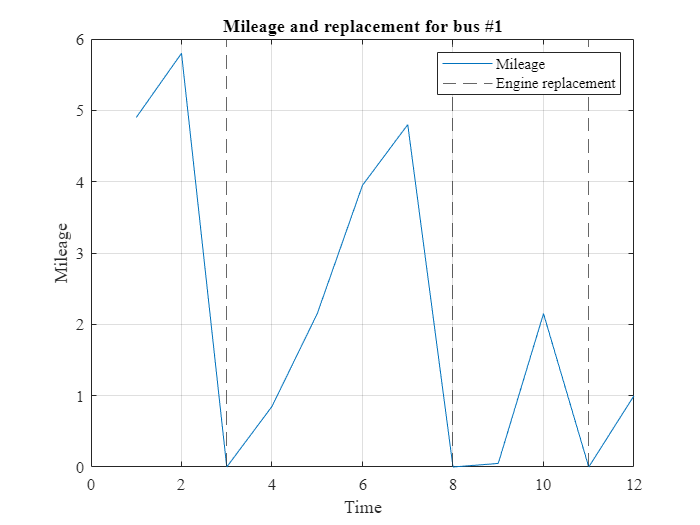

beta = 0.9;
theta = [2.00, -0.15, 1.0];
T=30;
S=1:2;
X=x;
N=2000;
pi=0.4; 
[data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, f, F, X,beta, pi, theta);


plot(data_t(1,1:12), data_x(1,1:12)); 
xline(data_t(1,data_x(1,1:12)==0),'--');
xlabel('Time'); ylabel('Mileage');title('Mileage and replacement for bus #1');
legend('Mileage','Engine replacement');

### 1.3 CCP estimation with unrestricted utility estimates

**Estimating the conditional choice probabilities. **

Our first step is to estimate the conditional choice probabilities. We can obtain the maximum likehood estimates by a simple frequency estimator:


$$\hat{p}_j(x) = \frac{\sum_{n=1}^N \sum_{t=1}^T \mathbf{1}\{x_{nt}=x, \ d_{jnt} = 1\}}{\sum_{n=1}^N \sum_{t=1}^T \mathbf{1}\{x_{nt}=x\}}$$


ccp_hat = zeros(length(X),length(S));
epsilon=1e-4;
for j=1:length(X)
    for s=1:length(S)
        %ccp_hat(j,s) = max(epsilon, min(1-epsilon,sum(data_d(data_x_index(:)==j & data_s(:)==s)==1)/sum(data_x_index(:)==j & data_s(:)==s)));
        ccp_hat(j,s) = sum(data_d(data_x_index(:)==j & data_s(:)==s)==1)/sum(data_x_index(:)==j & data_s(:)==s);
    end
end
never_reached=isnan(ccp_hat(:)); % keep track of states that never occur in the data
ccp_hat=max(epsilon, min(1-epsilon,ccp_hat)); % Makes sure that all probabilities are in the open interval (0,1), as "1" and "0" observations cause problems.


In practice, it is common to use a parametric first-stage and estimate the conditional choice probabilities with a flexible parametric or semi-parametric form. Here we use a logit with quadratic and interaction terms to estimate the conditional choice probabilities.

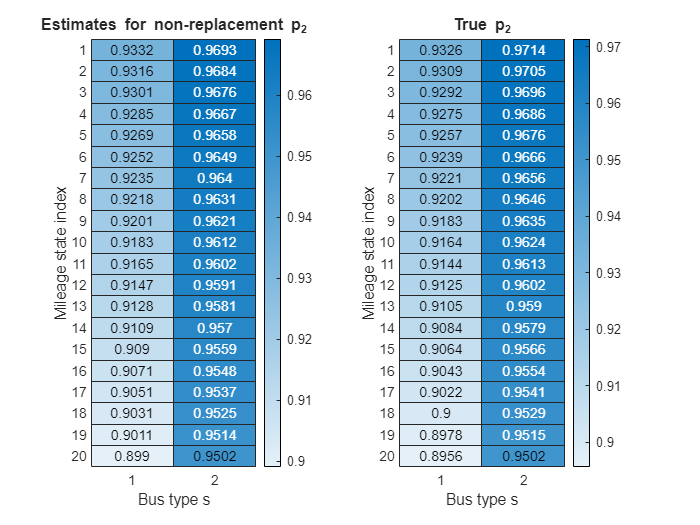

%
X_logit=[data_x(:) data_x(:).^2 (data_s(:)==2) (data_s(:)==2).*data_x(:)]';
lambda_hat = mnrfit(X_logit',data_d(:));

ccp_hat_logit=zeros(length(X),length(S));

for s=1:length(S)
    X_logit_fit=[X', X'.^2, (s==2)*ones(size(X,2),1), (s==2).*X' ];
    temp_ccps=mnrval(lambda_hat,X_logit_fit);
    ccp_hat_logit(:,s)=temp_ccps(:,1);
end

ccp_hat = ccp_hat_logit;

% Compare with true CCPs
[~,~,ccps_true] = value_function_iteration(S,F2,X, beta,theta);

figure(1);subplot(1,2,1);h=heatmap(1-ccp_hat(1:20,:));
h.Title='Estimates for non-replacement p_2';h.XLabel = 'Bus type s'; h.YLabel='Mileage state index';
subplot(1,2,2);h2=heatmap(1-ccps_true(1:20,:));
h2.Title='True p_2';h2.XLabel = 'Bus type s'; h2.YLabel='Mileage state index';

**Defining the estimator**

The estimator follows the moment condition formulation above, using the unrestricted utility estimates to develop a minimum distance estimator (Altug and Miller (1998)).

We estimate the unrestricted utility of not replacing the engine for each state according to

    $\mathbf{u}_2 = \Psi_1 - \Psi_2 -\mathbf{u}_1 + \beta \Big(F_1 - F_2 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1 + \mathbf{u}_1\Big)$, 

where $\Psi_1 = \left( \begin{array}{c} \gamma - \log(p_1(x^1)) \\ \vdots \\ \gamma - \log(p_1(x^M)) \end{array} \right)$, $\quad \Psi_2 = \left( \begin{array}{c} \gamma - \log(p_2(x^1)) \\ \vdots \\ \gamma - \log(p_2(x^M)) \end{array} \right)$, $\mathbf{u}_1$ is an $M \times 1$ vector of zeros, and $\mathbf{u}_2$ is an $M \times 1$ vector of utilities for choice 2.

The approach below does this sequentially for each of the two realizations of $s \in \{1,2\}$.

u2_unres(:,1) = log(1-ccp_hat(:,1))-log(ccp_hat(:,1))+beta*(F1 - F2)*((eye(length(X)) - beta*F1)\(emc-log(ccp_hat(:,1))));
u2_unres(:,2) = log(1-ccp_hat(:,2))-log(ccp_hat(:,2))+beta*(F1 - F2)*((eye(length(X)) - beta*F1)\(emc-log(ccp_hat(:,2))));

Finally, we define a weighting matrix $W$ and estimate the parameters so as to minimize the weighted squared deviation. 


$$\hat{\theta}_{MD} = \arg \min_{\theta} \Big[ \mathbf{u}_2(\mathbf{x};\theta) - \hat{\mathbf{u}}_2\Big]' W \Big[ \mathbf{u}_2(\mathbf{x};\theta) - \hat{\mathbf{u}}_2\Big]$$


where $\mathbf{u}_2(\mathbf{x};\theta) = \left(\begin{array}{c} u_2(x^1;\theta) \\ \vdots \\ u_2(\overline{x};\theta) \end{array} \right)$ and $\mathbf{\hat{u}}_2 = \left(\begin{array}{c} \hat{u}_2(x^1) \\ \vdots \\ \hat{u}_2(\overline{x}) \end{array} \right)$ are vectors of the utilities associated with each state. 

In the case of linear utility specifications, which covers many of the applications used in practice, we can specify this as a linear estimator and express the estimator in closed form. For instance, we can use the normal OLS estimator to get consistent estimates:


$$\hat{\theta}_{MD} = (\mathbf{X}' * \mathbf{X})^{-1} \mathbf{X}' \mathbf{\hat{u}}_2$$



all_states = [X', ones(length(X),1); X', 2*ones(length(X),1)];
X_reg=[ones(size(all_states,1),1), all_states];
Y_reg=u2_unres(:);
ThetaHat_MinDist=(X_reg'*X_reg)\(X_reg'*Y_reg);
MinimumDistanceEstimates = table(ThetaHat_MinDist,theta','VariableNames',{'Min. Dist. CCP estimates','True values'})

MinimumDistanceEstimates = 3×2 table
    Min. Dist. CCP estimates    True values
    ________________________    ___________

              2.0668                   2   
            -0.13133               -0.15   
             0.88276                   1   


*Note: *If we have a non-linear utility function we can use a similar approach. The code example below shows a stylized setup.

Note that in general, we want to account for the sampling error in the first stage: the components of $\mathbf{\hat{u}}_2$ depend on the first-stage estimates for the conditional choice probabilities, so it is recommended to choose a weighting matrix that accounts for this uncertainty, in which the weights will depend on the sample standard deviation of the estimates for $\mathbf{\hat{u}}_2$ (see Remark 5 of Kalouptsidi et al. (2021)). I won't go into too much detail on this here, as many other sources discuss optimal weighting matrices in these settings. A simple step in the right direction is to weight each moment by the number of observations in the data that correspond to that moment.


states_num=zeros(size(all_states,1),1);
for j=1:size(states_num,1)
    states_num(j)=sum(data_x(:)==all_states(j,1) & data_s(:)==all_states(j,2));
end
W = diag(states_num./(size(data_d(:),1)));

ThetaHat_MinDist_Weighted = (X_reg'*W*X_reg)\(X_reg'*W*Y_reg);
NoWeightDistanceEstimates = table(ThetaHat_MinDist_Weighted,theta','VariableNames',{'Weighted min. dist. estimates','True values'})

NoWeightDistanceEstimates = 3×2 table
    Weighted min. dist. estimates    True values
    _____________________________    ___________

                2.0855                      2   
              -0.14435                  -0.15   
               0.91253                      1   


### 1.4 Full-information maximum likelihood estimation 

For reference, we also include a full information maximum likelihood estimation routine based on the nested fixed point. This version is simple to code but computationally very slow; however, it gives a sense of how close the CCPs estimate are to a fully efficient benchmark.

fiml_fun = @(theta) FIML_log_likelihood(theta,data_x,data_s,data_d,X,S,data_x_index,f,beta);

theta_0=0.1*ones(3,1);
options = optimoptions('fminunc','Display','none');
[theta_hat,~] = fminunc(fiml_fun,theta_0,options);
FIML_EstimatesTable = table(theta_hat,theta','VariableNames',{'FIML estimates','True values'})

FIML_EstimatesTable = 3×2 table
    FIML estimates    True values
    ______________    ___________

         2.0159              2   
       -0.14946          -0.15   
          1.006              1   


## Functions

### Data generation

function [data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, x_tran, x_tran_cumul, X, beta,pi,theta)
    
    initial_run=5; % We start the state variables at zero and let the model run for five periods before we start sampling
    x_index = ones(N, T+initial_run); 
    x_sim = zeros(N,T+initial_run);
    
    s_sim  = (rand(N,1) > pi) + 1;
    d_sim  = zeros(N, T+initial_run); 
    draw_ccp = rand(N, T+initial_run);
    draw_x  = rand(N, T+initial_run);

    value_function = value_function_iteration(S,x_tran,X,beta, theta);
    for n = 1:N
        for t = 1:T+initial_run
            % j=1 replace 
            u1 = 0.0;
            v1 = u1 + beta*value_function(1,s_sim(n)); % Reset to zero mileage deterministically if engine is replaced.
            % j=2 is continue
            u2 = theta(1) + theta(2) * X(x_index(n,t)) + theta(3) * s_sim(n);
            v2 = u2 + beta* x_tran(x_index(n,t),:)*value_function(:,s_sim(n));
            
            % Conditional choice probability
            p1 = exp(v1)/(exp(v1)+exp(v2)); 

            % Simulate next period
            d_sim(n,t)    = (draw_ccp(n,t) > p1) + 1; % 1: replace, 2: continue
            x_index(n,t+1) = (d_sim(n,t)==2) * sum((draw_x(n,t) > x_tran_cumul(x_index(n,t),:))) + 1; 
            x_sim(n,t+1) = X(x_index(n,t+1));
        end
    end
    
    data_x = x_sim(:, initial_run+1:T+initial_run);
    data_d = d_sim(:, initial_run+1:T+initial_run);
    data_s = repmat(s_sim,  [1,T]);
    data_t = repmat(transpose(1:T), [1,N])';
    [~, data_x_index] = ismember(data_x,X); 
    
    return 

end


### Full-information maximum likelihood

function [fiml_lik] = FIML_log_likelihood(theta,data_x,data_s,data_d,X,S,data_x_index,x_tran,beta)

value_function = value_function_iteration(S,x_tran,X,beta,theta);

D_temp = data_d(:);
S_temp = data_s(:);
X_index_temp = data_x_index(:);

v1 = repmat(beta*value_function(1,S),[length(X),1]);
v2 = theta(1) + theta(2)*X' + theta(3)*S + beta*(x_tran(:,:)*value_function(:,:));

x_s_index    = sub2ind(size(v2), X_index_temp, S_temp);
fiml_lik = -sum((D_temp==2).*(v2(x_s_index)-v1(x_s_index)) - log(1+exp(v2(x_s_index)-v1(x_s_index))));

end

### Value function iteration

function [value_function,value_diff,ccps] = value_function_iteration(S,x_tran,X, beta,theta)
x_len = length(unique(X));
emc = double(eulergamma);
value_function_2 = zeros(x_len,length(S));
ccps=zeros(x_len,length(S));
value_diff=1;
max_iter=1000;
iter=1;
while value_diff>1e-5 && iter < max_iter
    value_function_1 = value_function_2;
    for s=1:length(S)
                v1 = repmat(beta*value_function_1(1,s),[x_len,1]);
                v2=theta(1) + theta(2)*X' + theta(3)*s + beta*(x_tran(:,:)*value_function_1(:,s));
                value_function_2(:,s) = log(exp(v1)+exp(v2)) + emc;
                ccps(:,s)=1./(1+exp(v2-v1));
    end
    iter=iter+1;
    value_diff = max(max((value_function_2 - value_function_1).^2));
end
value_function = value_function_2;
end


## References

Abbring, J. H., & Daljord, Ø. (2020). [Identifying the discount factor in dynamic discrete choice models](https://www.econometricsociety.org/publications/quantitative-economics/2020/05/01/Identifying-the-discount-factor-in-dynamic-discrete-choice-models). *Quantitative Economics*, *11*(2), 471-501.

Altuğ, S., & Miller, R. A. (1998). [The effect of work experience on female wages and labour supply](http://www.comlabgames.com/ramiller/effect_workexp_femaleWage_laborSupply1998.pdf). *The Review of Economic Studies*, *65*(1), 45-85.

Arcidiacono, P., & Ellickson, P. B. (2011). [Practical methods for estimation of dynamic discrete choice models](https://www.researchgate.net/profile/Paul-Ellickson/publication/228313050_Practical_Methods_for_Estimation_of_Dynamic_Discrete_Choice_Models/links/0912f50db1b686c65a000000/Practical-Methods-for-Estimation-of-Dynamic-Discrete-Choice-Models.pdf). *Annu. Rev. Econ.*, *3*(1), 363-394.

Arcidiacono, P., & Miller, R. A. (2011). [Conditional choice probability estimation of dynamic discrete choice models with unobserved heterogeneity](http://public.econ.duke.edu/~psarcidi/ccp0810.pdf). *Econometrica*, *79*(6), 1823-1867.

Kalouptsidi, M., Scott, P. T., & Souza-Rodrigues, E. (2021).[ Linear IV regression estimators for structural dynamic discrete choice models.](https://www.nber.org/system/files/working_papers/w25134/w25134.pdf) *Journal of Econometrics*, *222*(1), 778-804.

Keane, M. P., & Wolpin, K. I. (1997). [The career decisions of young men](https://www.researchgate.net/profile/Michael-Keane-8/publication/24103974_The_Career_Decisions_of_Young_Men/links/09e415074aada5b3b7000000/The-Career-Decisions-of-Young-Men.pdf). *Journal of political Economy*, *105*(3), 473-522.

Magnac, T., & Thesmar, D. (2002). [Identifying dynamic discrete decision processes](https://editorialexpress.com/jrust/econ615/readings/magnac_thesmar_econometrica_2002.pdf). *Econometrica*, *70*(2), 801-816.

Rust, J. (1987). [Optimal replacement of GMC bus engines: An empirical model of Harold Zurcher](https://editorialexpress.com/jrust/crest_lectures/zurcher.pdf). *Econometrica: Journal of the Econometric Society*, 999-1033.